# Loading a .stl file format

gmdl = Gmodel('Bunny.stl');

* Loaded mesh = <a href="">Bunny.stl
</a>* Vertices  = 43.32k 
* Polycount = 86.63k 


# Baking the vertex normals

Before we can show the .stl, we have to *'bake' *the texture. This implies for every `gmdl.Node` and `gmdl.Elements`, we need to compute the normals. **We only need to bake once! **

gmdl.bake(); % baking the graphical model

# Material captures and Textures -- MatCaps

In SOROTOKI, we use so-called **Material Captures - MatCaps** in short. These are spherical textures mapped onto an [NxNx3] RBG matrix. Every instance of the class Gmodel.m will have a base texture; called `base.m`, which can be accessed under `gmdl.Texture`. As an illustrative example, let svisualize how these MatCaps look:

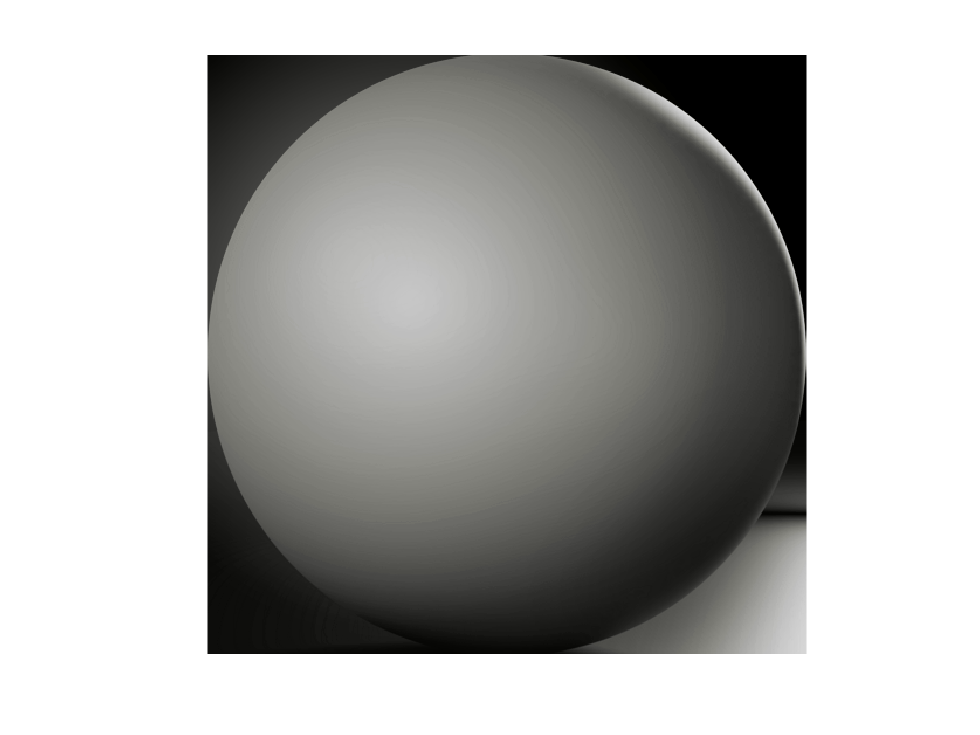

image(gmdl.Texture); 
axis equal; 
axis off;

# Rendering the model

Once baking is done, we can render the graphics of the 3D-model. This will produce a figure with name '101'.

gmdl.render();  % rendering the graphics

Let's re-orient the figure

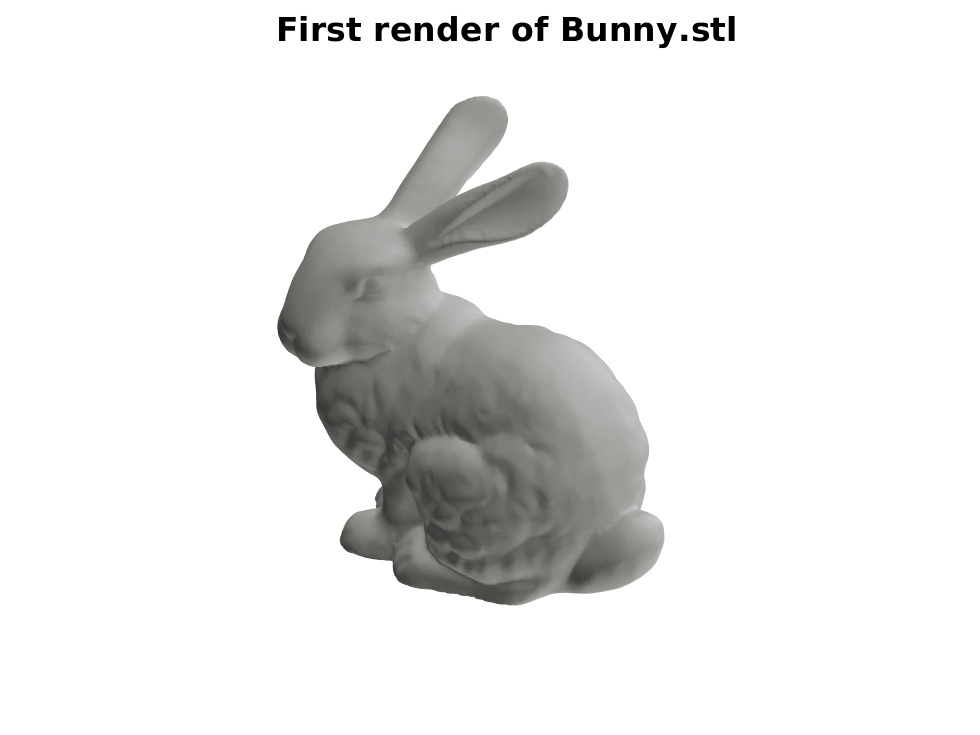

view(30,30);
title('First render of Bunny.stl','FontSize',25);

**Wait? Why are the shadows upside down?** The reason is that once the viewing angle of the figure is changed, the associated textures of the model need updating aswell. There is no need to bake again, since associated normals of the Mesh have not changed! We do need to recompute the innerproduct between the view direction and surface normals!

# Updating the texture

To update the texture, we need to call `gmdl.update`. Alternatively, we can rotate the model using the **Rotate 3D icon** in the Figure(101). This will automatically call `gmdl.update()`.

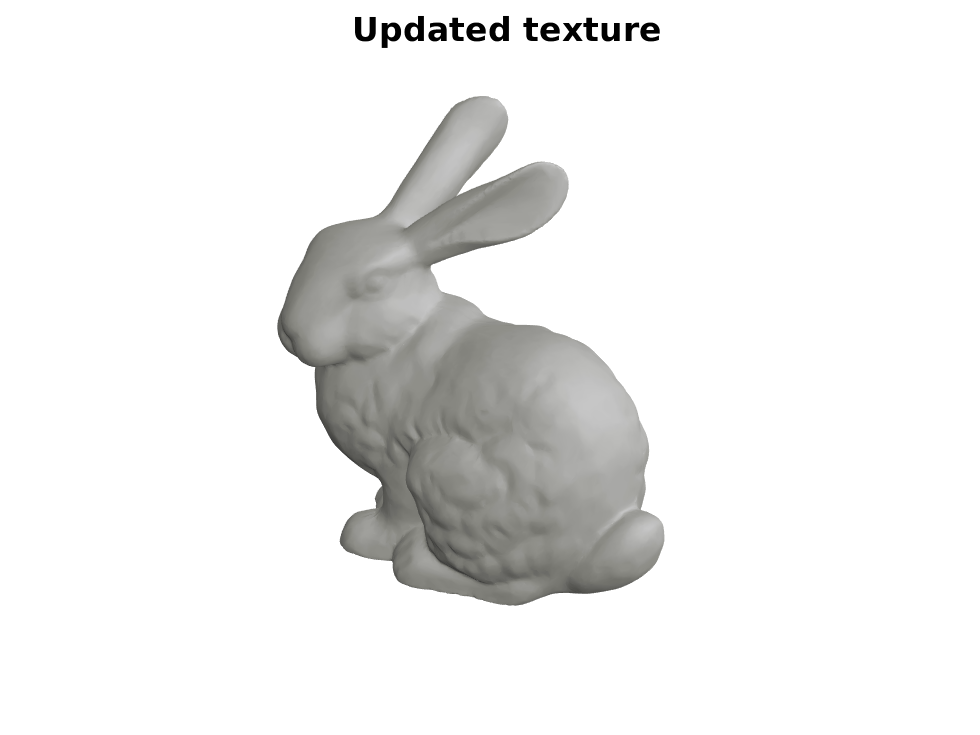

gmdl.update();
title('Updated texture','FontSize',25);

# Changing the texture

As mentioned earlier, the texure of the models can be accessed through gmdl.Texture -- which is an [NxNx3] integer array (RBG matrix). To change a texture, we simply do the following:

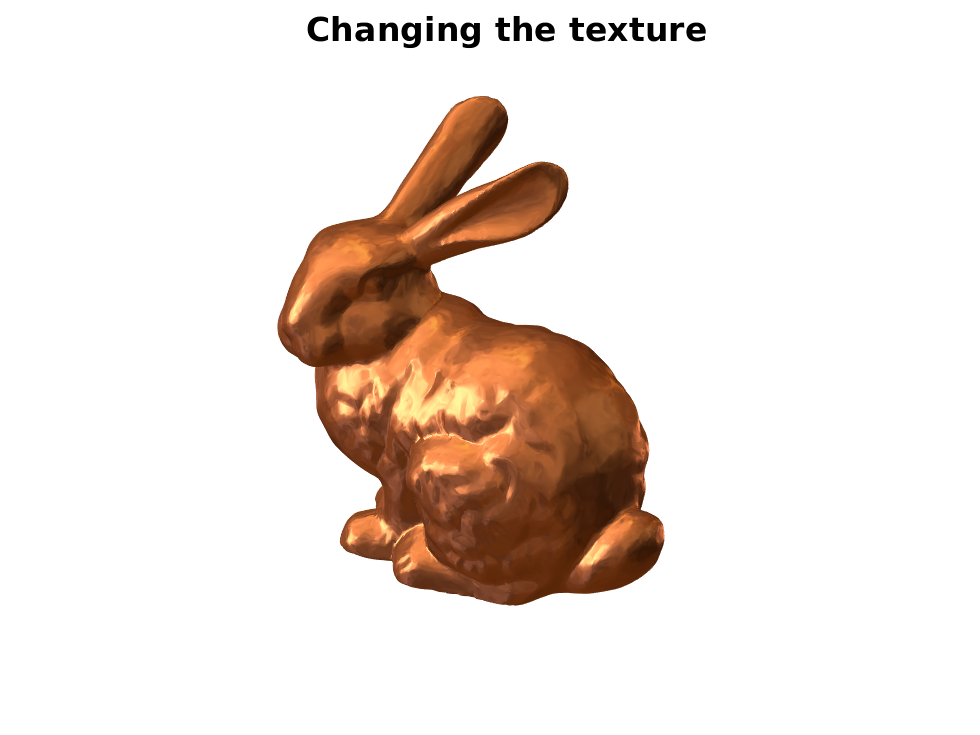

gmdl.Texture = copper;
gmdl.update();
title('Changing the texture','FontSize',25);